**AFSAH  HYDER**

**LAB 03**

**Activity 1**

A=2 ; fo=4;
fs=10*fo; Ts=1/fs

Ts = 0.0250

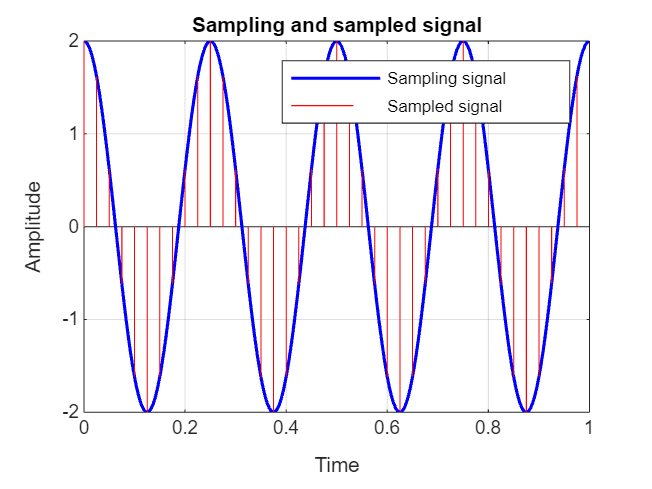

M=6;
T_Delta = Ts/M;
C=100;

To= 1/fo;
Tmax = To*C; % The maximum value of time
t = linspace(0,Tmax,round(Tmax/T_Delta)); % The time axis
xt = A*cos(2*pi*fo*t);  %signal

data_points = length(xt); % Number of data points in x(t)
xSt = zeros(1, data_points); % The Sampled signal is initialized with zeros
xSt(1:M:end) = xt(1:M:end); % The Sampled signal as specified above

figure; % Open a new figure window
plot(t, xt, 'b', 'LineWidth', 1.5); xlim([0 1]);
hold on; 
h=stem(t, xSt, 'r');  xlim([0 1]); set(h, 'Marker', 'none');
hold off;

xlabel('Time');
ylabel('Amplitude');
legend('Sampling signal', 'Sampled signal');
title('Sampling and sampled signal');
grid on;

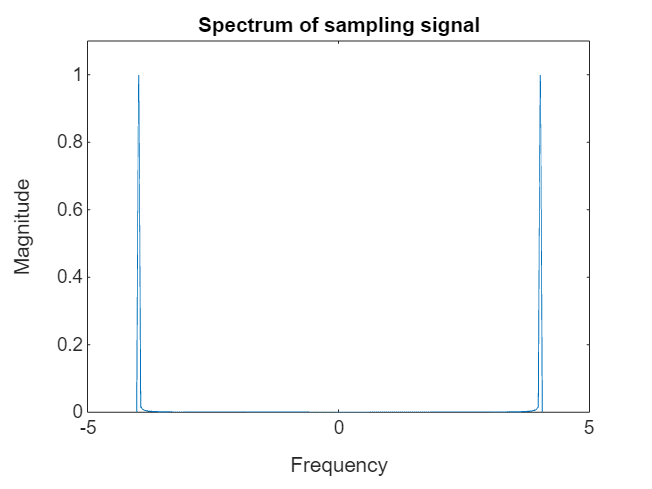


Xf= T_Delta/Tmax * fftshift(fft(xt));
XSf= 1/Tmax * fftshift(fft(xSt));
N = length(xt);
f = linspace(-M*fs/2, M*fs/2,N);

plot(f,Xf) ; ylim([0 1.1]); xlabel("Frequency"); ylabel("Magnitude"); title("Spectrum of sampling signal");

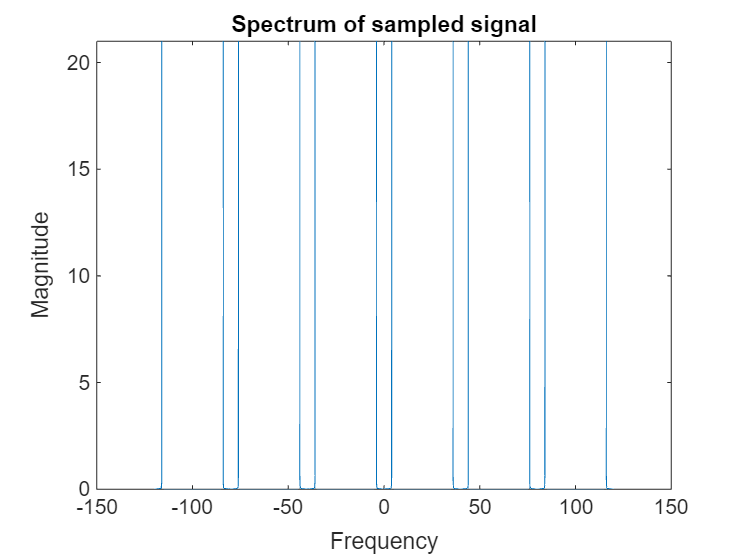

plot(f,XSf); ylim([0 21]); xlabel("Frequency"); ylabel("Magnitude"); title("Spectrum of sampled signal");

I first started fs=5*fo, which means a smaller sampling frequency, so when i did task 2, the reconstructed signal was inaccurate. This led me to increase the sampling frequency, until the reconstructed signal seemed reasonable enough, so i ended up with fs=10*fo.

**Key Observations:**

- If M is large, fewer samples are taken, which might lead to loss of information.

- If M is small, more samples are captured, closely resembling the original signal.

We have to find a balance between the two, so the key information of the signal is captured without wasting storage.

** Spectrum of the Sampling Signal **

- The spectrum clearly shows two peaks at ±4 Hz, which is the fundamental frequency of the cosine wave.

- The magnitude is normalized properly, with peaks at 1.

**Spectrum of the Sampled Signal**

- The peaks are now repeated at multiples of the sampling frequency fs=40 Hz.

- There are peaks at ±4, ±36, ±76, ±116, etc., which is expected due to spectral replication in sampling.

**Activity 2**

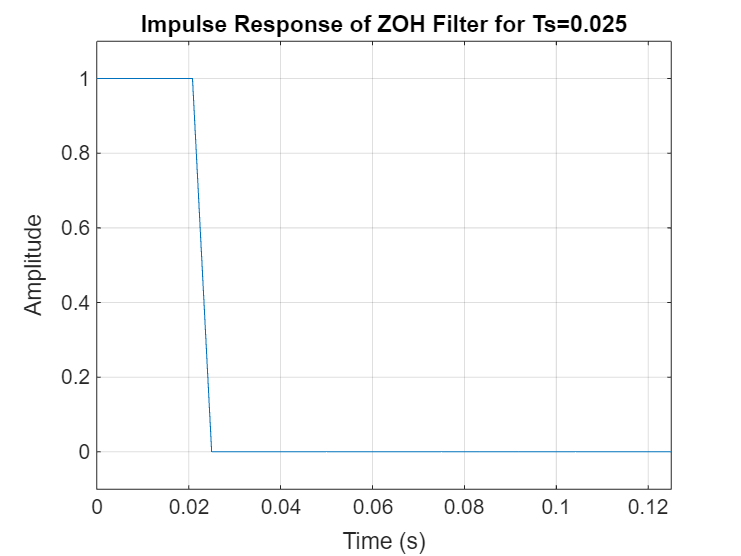

% ZOH Impulse Response
hzoh = (t >= 0) & (t < Ts); 

% Plot Impulse Response
figure;
plot(t, hzoh); xlabel('Time (s)'); ylabel('Amplitude'); title('Impulse Response of ZOH Filter for Ts=0.025');
grid on;
ylim([-0.1, 1.1]); xlim([0 Ts+0.1]); 

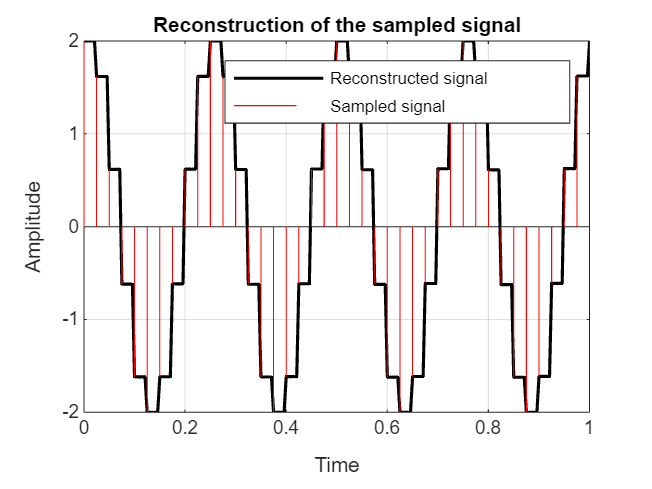


% Apply ZOH filtering
xZOH = filter(hzoh, 1, xSt);

figure; % Open a new figure window
plot(t, xZOH, 'k', 'LineWidth', 1.5); xlim([0 1]);
hold on; 
h=stem(t, xSt, 'r');  xlim([0 1]); set(h, 'Marker', 'none');
hold off;

xlabel('Time');
ylabel('Amplitude');
legend('Reconstructed signal', 'Sampled signal');
title('Reconstruction of the sampled signal');
grid on;

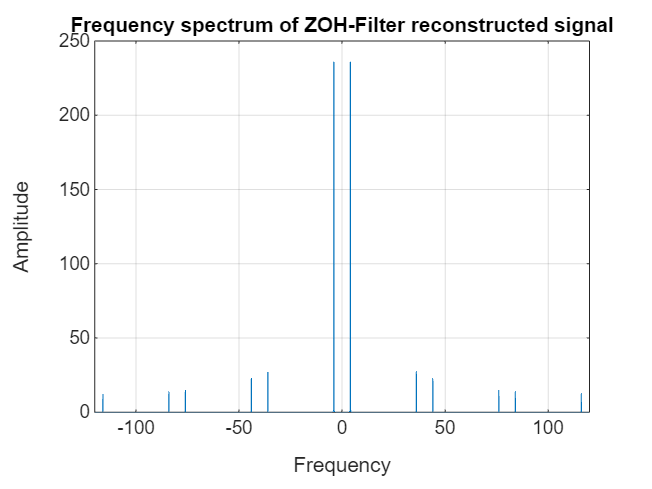



xZOHf = 1/Tmax * fftshift(fft(xZOH));
plot(f,abs(xZOHf)); xlabel("Frequency"); ylabel("Amplitude"); 
grid on; title("Frequency spectrum of ZOH-Filter reconstructed signal");

The ZOH impulse response stays at 1 for the sample period Ts=0.025 seconds and then drops to 0. This is expected because ZOH holds the value constant for the duration of the sampling period before switching to the next value.

In the time domain, the black signal represents the ZOH-reconstructed signal, which steps between values instead of instantaneous changes. Each sample is held constant until the next sample is taken, creating a staircase effect.

The frequency spectrum shows a sharp peak at the fundamental frequency fo=4 Hz, which confirms the presence of the original signal, this spectrum was that of the original signal in activity 1. However, there are additional harmonics (side lobes) due to the ZOH operation. These harmonics occur because ZOH acts as a low-pass filter, smoothing out the signal but also introducing high-frequency components due to the step changes in the reconstructed signal. The magnitude at DC (0 Hz) is much higher, which is expected because ZOH reconstruction introduces a DC bias in the signal.

The simulated sidebands aligned with the theoretical prediction from eq 1.

**Activity 3**

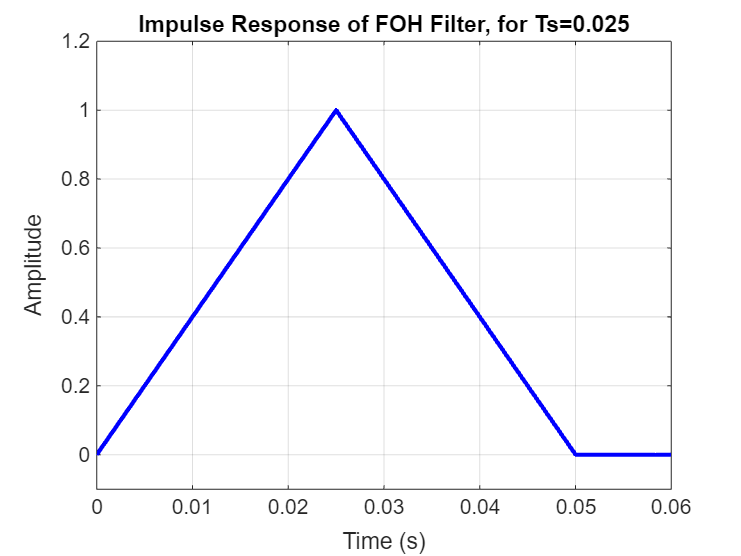

% Define the piecewise function h_foh(t)
h_foh = zeros(size(t)); % Initialize h_foh with zeros

h_foh((t >= 0) & (t < Ts)) = t((t >= 0) & (t < Ts)) / Ts;
h_foh((t >= Ts) & (t < 2*Ts)) = 2 - t((t >= Ts) & (t < 2*Ts)) / Ts;

% Plot the function
plot(t, h_foh, 'b', 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Amplitude'); title('Impulse Response of FOH Filter, for Ts=0.025');
grid on; ylim([-0.1, 1.2]); xlim([0 2*Ts+0.01]);

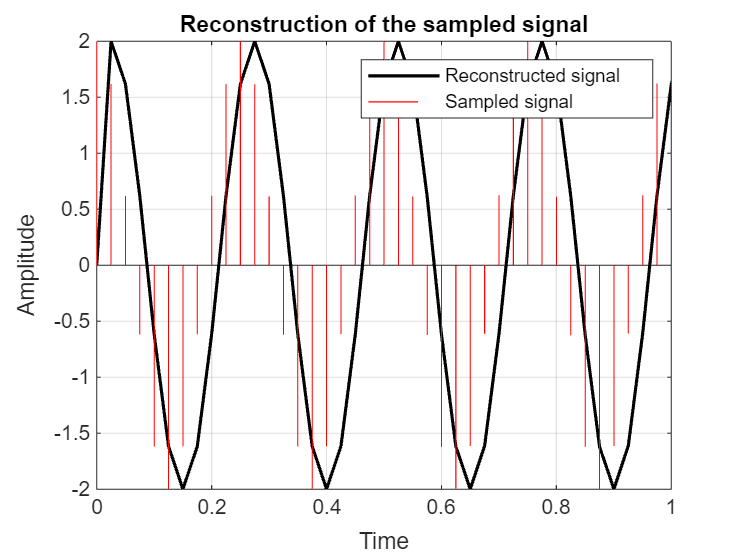


% Apply FOH filtering
xFOH = filter(h_foh, 1, xSt);

figure; % Open a new figure window
plot(t, xFOH, 'k', 'LineWidth', 1.5); xlim([0 1]);
hold on; 
h=stem(t, xSt, 'r');  xlim([0 1]); set(h, 'Marker', 'none');
hold off;

xlabel('Time');
ylabel('Amplitude');
legend('Reconstructed signal', 'Sampled signal');
title('Reconstruction of the sampled signal');
grid on;

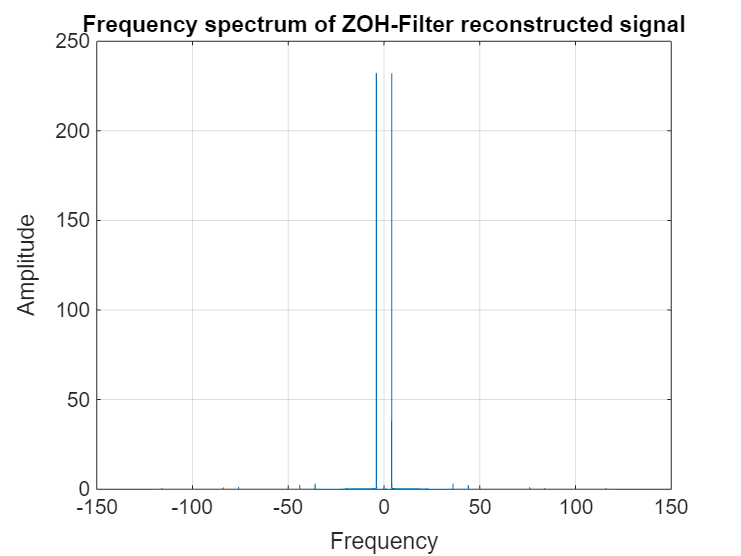


xZOHf = 1/Tmax * fftshift(fft(xFOH));
plot(f,abs(xZOHf)); xlabel("Frequency"); ylabel("Amplitude"); 
grid on; title("Frequency spectrum of ZOH-Filter reconstructed signal");

**Impulse response of FOH:** 

- Interpolates between consecutive samples using a linear function, forming a triangular impulse response.

- The response starts from zero, rises linearly to a peak at the sampling interval Ts=0.025, and then falls linearly back to zero.

**Reconstruction in time domain:    **

- FOH interpolates linearly between adjacent points.

- This results in a more natural approximation of the original continuous-time signal

**Reconstruction in frequency domain:  **

- There is a significant frequency component at 4Hz, since that was the natural frequency of the original signal

- There are also other higher frequency components, but attenuated more effectively compared to ZOH.

- The residual spectral components still remain due to the discrete nature of sampling.

- The simulated sidebands aligned with the theoretical prediction from eq 2. (they have lesser magnitude too)

**Comparision of ZOH and FOH**

- FOH provides better signal reconstruction than ZOH by reducing staircasing effects.

- The linear interpolation between samples leads to improved frequency response and reduced aliasing.

- The FOH reconstructed signal is a closer replica of the original signal.

- Despite this, some distortions remain, making further filtering necessary for high-accuracy applications.

**Activity 4**

% Define Raised-Cosine Impulse Response
beta = 0.25;  % Roll-off factor
t = linspace(-Tmax,Tmax,round(Tmax/T_Delta)); % The time axis
hrc = zeros(size(t)); % Initialize h_rc
% Special case when t = ± Ts/(2β) to avoid division by zero
t_special = Ts / (2 * beta);
idx_special = abs(t - t_special) < 1e-6 | abs(t + t_special) < 1e-6;
hrc(idx_special) = (pi / (4 * Ts)) * sinc(1 / (2 * beta));

% General case
idx_general = ~idx_special;
numerator = sinc(t(idx_general) / Ts) .* cos(pi * beta * t(idx_general) / Ts);
denominator = 1 - (2 * beta * t(idx_general) / Ts).^2;
hrc(idx_general) = (1 / Ts) * (numerator ./ denominator);
hrc= hrc/max(hrc)

hrc =     0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000


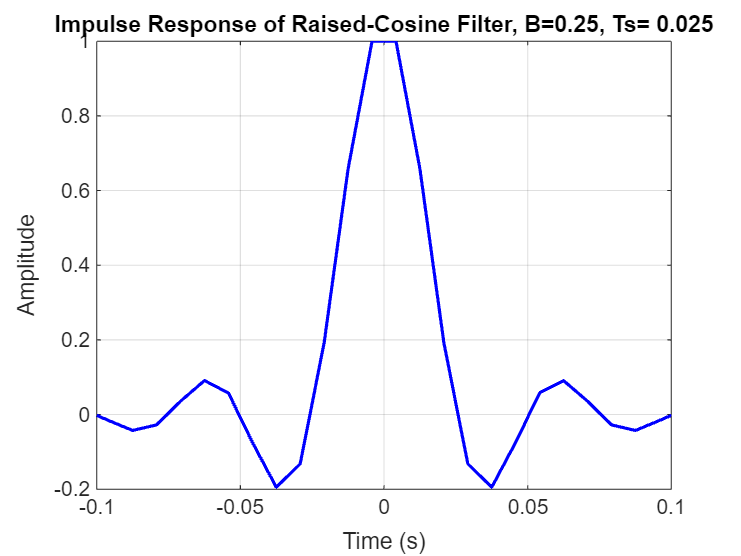

% Plot the Raised-Cosine Impulse Response
figure;
plot(t, hrc, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response of Raised-Cosine Filter, B=0.25, Ts= 0.025');
grid on;
xlim([-0.1 0.1]); % Set time axis limits for better visualization

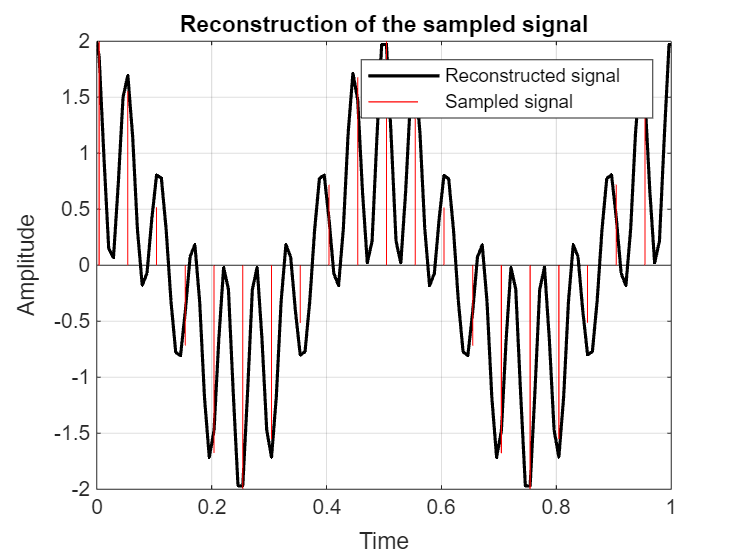


% Apply FOH filtering
xRCOH = filter(hrc, 1, xSt);

figure; % Open a new figure window
plot(t, xRCOH, 'k', 'LineWidth', 1.5); xlim([0 1]);
hold on; 
h=stem(t, xSt, 'r');  xlim([0 1]); set(h, 'Marker', 'none');
hold off;

xlabel('Time');
ylabel('Amplitude');
legend('Reconstructed signal', 'Sampled signal');
title('Reconstruction of the sampled signal');
grid on;

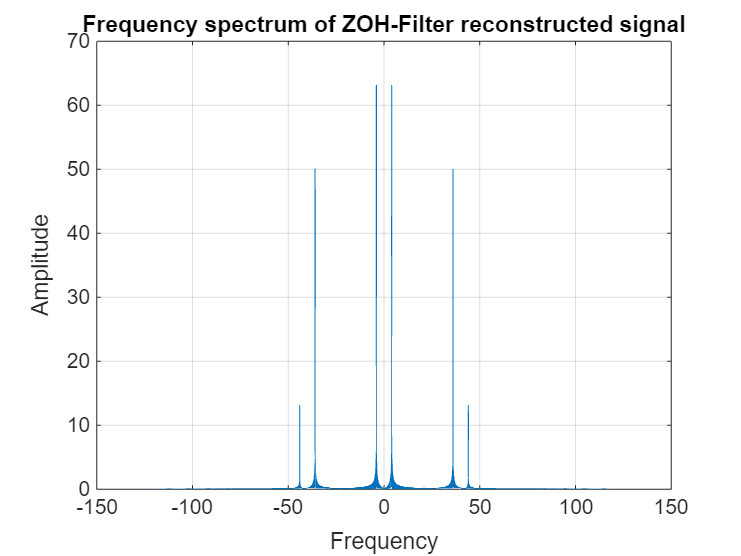


xRCOHf = 1/Tmax * fftshift(fft(xRCOH));
plot(f,abs(xRCOHf)); xlabel("Frequency"); ylabel("Amplitude"); 
grid on; title("Frequency spectrum of ZOH-Filter reconstructed signal");

**. Impulse Response of Raised-Cosine Filter**

- The impulse response exhibits a smooth, oscillatory decay, characteristic of the raised-cosine filter.

- The central peak at t=0 corresponds to the primary contribution, with side lobes gradually decreasing in amplitude.

- The roll-off factor B=0.25 controls the bandwidth, allowing a balance between smoothness and transition sharpness.

** Reconstructed Signal**

- The reconstructed signal is like the sampled signal much more closely than both ZOH and FOH.

- Unlike ZOH (which introduces staircasing) and FOH (which linearly interpolates), the raised-cosine filter uses a sinc-like smoothing effect, significantly reducing high-frequency artifacts.

- The offset visible in the FOH reconstructed signal is also barely noticeable here.

- The resulting waveform maintains continuity and more accurately represents the original analog signal.